clf;
% create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.2*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2*log(sqrt((x-1.41).^2 + (y+2).^2));

% define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.37).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
axis equal;


$$V\left(x,y\right)=20*\ln \sqrt{{\left(x-0\ldotp 75\right)}^2 +{\left(y+2\ldotp 5\right)}^2 }-2*\ln \sqrt{{\left(x+0\ldotp 25\right)}^2 +{\left(y+1\right)}^2 }-2*\ln \sqrt{{\left(x-1\ldotp 41\right)}^2 +{\left(y+2\right)}^2 }-0\ldotp 2*\ln \sqrt{{\left(x-1\right)}^2 +{\left(y+0\ldotp 7\right)}^2 }$$


% surface plot
surf(x, y, v);

% quiver plot
clf;
% create a meshgrid
[x,y]=meshgrid(-1.5:0.03:3,-4:0.03:2);

fx = ((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - ((x+0.25)./((x+0.25).^2+(y+1).^2)) - ((x-1.41)./((x-1.41).^2+(y+2).^2)) - ((x-1)./((x-1).^2+(y+0.7).^2));
fy = ((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - ((y+1)./((x+0.25).^2+(y+1).^2)) - ((y+2)./((x-1.41).^2+(y+2).^2)) - ((y+0.7)./((x-1).^2+(y+0.7).^2));

for a = -1.5:0.5:2.5
    fx = fx - ((x-a)./((x-a).^2 + (y-1).^2));
    fy = fy - ((y-1)./((x-a).^2 + (y-1).^2));

    fx = fx - ((x-a)./((x-a).^2 + (y+3.37).^2));
    fy = fy - ((y+3.37)./((x-a).^2 + (y+3.37).^2));
end

for b = -4:0.5:2
    fx = fx - ((x+1.5)./((x+1.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x+1.5).^2 + (y-b).^2));
 
    fx = fx - ((x-2.5)./((x-2.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x-2.5).^2 + (y-b).^2));
end
quiver(x,y,fx,fy,20)
axis equal

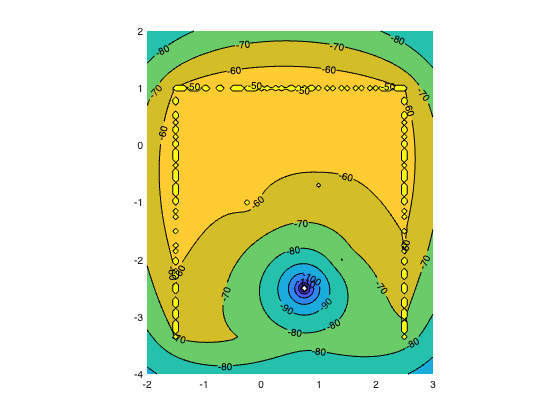

% Descent plot:
clf;
hold on;

% create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.2*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2*log(sqrt((x-1.41).^2 + (y+2).^2));

% define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.37).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
xlabel("")
axis equal;


streamline(x, y, v)

Error using streamline>parseargs
Wrong number of input arguments.

Error in streamline (line 51)
[verts, x, y, z, u, v, w, sx, sy, sz, options] = parseargs(nargs,args);